##  Задание 3. Модальное управление по выходу. 

Начальные условия на задание:

A = [5 -7 -5 1;
    -7 5 -1 5;
    -5 -1 5 7;
    1 5 7 5]

A =      5    -7    -5     1
    -7     5    -1     5
    -5    -1     5     7
     1     5     7     5


B = [5 7 1 9]'

B =      5
     7
     1
     9



C = [ 0 0 2 2;
     1 1 -1 -1]

C =      0     0     2     2
     1     1    -1    -1


D = [4 2]'

D =      4
     2


Найти собственные числа матрицы A и определить управляемость каждого из них. Сделать вывод об управляемости и стабилизируемости системы.

U = [B , A*B , A^2 * B, A^3 * B];
U = ctrb(A, B);
rank(U)

ans = 4



V = obsv(A, C)

V =            0           0           2           2
           1           1          -1          -1
          -8           8          24          24
           2          -6         -18          -6
        -192         192         320         320
         136         -56        -136        -184
       -3584        3584        4608        4608
        1568       -2016       -2592       -2016


V = [C ; C*A ; C*A^2 ; C*A^3];
rank(V)

ans = 4

**Управляемая + стабилизируема**

**Наблюдаема+обнаруживаема**

Проверка критерия Хаутуса:

eig(A)

ans =    -8.0000
    4.0000
    8.0000
   16.0000


l1 = -8; l2 = 4; l3 = 8; l4 = 16;

[A - eye(4).*l1 , B]

ans =     13    -7    -5     1     5
    -7    13    -1     5     7
    -5    -1    13     7     1
     1     5     7    13     9


[A - eye(4).*l2 , B]

ans =      1    -7    -5     1     5
    -7     1    -1     5     7
    -5    -1     1     7     1
     1     5     7     1     9


[A - eye(4).*l3 , B]

ans =     -3    -7    -5     1     5
    -7    -3    -1     5     7
    -5    -1    -3     7     1
     1     5     7    -3     9


[A - eye(4).*l4 , B]

ans =    -11    -7    -5     1     5
    -7   -11    -1     5     7
    -5    -1   -11     7     1
     1     5     7   -11     9



rank([A - eye(4).*l1 , B])

ans = 4

rank([A - eye(4).*l2 , B])

ans = 4

rank([A - eye(4).*l3 , B])

ans = 4

rank([A - eye(4).*l4 , B])

ans = 4

Теперь нужно синтезировать регулятор + наблюдателя для пары желаемых спектров, выбираем сами...

Для каждого спектра...


[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)
double(Aj2)

P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

G = [-4 1 0 0;
      0 -4 1 0;
      0   0  -4 1;
      0    0   0 -4]
Y = [0 1 0 1]'


Q = sylvester(G, -A, Y*C);
L = pinv(Q) * Y
eig(A + L*C)

% cvx_setup
%%%%%%%%%%%%%%%% - find K
cvx_begin sdp
variable Q(4,4)
G * Q - Q * A == Y*C;
cvx_end
L = pinv(Q)*Y
eig(A+L*C)
%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%% - find L
cvx_begin sdp
variable Q(4,4)
G * Q - Q * A == Y*C;
cvx_end
L = pinv(Q)*Y
eig(A+L*C)
%%%%%%%%%%%%%%%%

% t1 = 6;
% time = linspace(0, t1, 1000);
% x0 = [1; 1; 1; 1]';        % plant
% x_hat0 = [2; 0; 0; -1]';   % observer
% 
% sys_plant = ss(A, [0 0 0 0]', C, []);
% 
% u_plant = zeros(size(time));
% [y_hat1, t1, x_real] = lsim(sys_plant, u_plant, time, x0);
% 
% sys_obs = ss(A + L*C + B*K + L*D*K, -L, C, []);
% 
% y_plant = C*x_real';
% 
% [y_hat2, t2, x_obs] = lsim(sys_obs, y_plant, time, x_hat0);
% 
% 
% h = figure;
% set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% plot(time, y_hat1, 'g', 'LineWidth', 1.5); hold on;
% plot(time, y_hat2, 'r--', 'LineWidth', 1.0); 
% grid on;
% xlabel('time [s]');                                   
% legend('$y_{plant}(t)$','$y_{obs}(t)$', ...
%         'Location', 'best', 'Interpreter', 'latex');
% save_file("obsv_eigen1");
% 
% h = figure;
% set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% plot(time, abs(y_hat1-y_hat2), 'g', 'LineWidth', 1.5); hold on;
% grid on;
% xlabel('time [s]');                                   
% legend('$y_{error}(t)$', ...
%         'Location', 'best', 'Interpreter', 'latex');
% save_file("obsv_error_eigen1");

P =   -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


P2 =    -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 =     -2     0     0
     0     3    -3
     0     3     3


Aj1 =     -2     0     0
     0     3     3
     0    -3     3


A_reduced =      3     3
    -3     3


B_reduced =      1
    -7


Y =      1     0


K =     0.5467    1.5067


ans =    -2.0000
   -2.0000


K_pad =          0    0.5467    1.5067


K =     1.0933   -2.0533    1.0933


ans =   -2.0000 + 0.0000i
  -2.0000 - 0.0000i
  -2.0000 + 0.0000i


G =     -2     1     0
     0    -2     1
     0     0    -2


Y =      1     1     1


Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


K =     1.0933   -2.0826    1.0641


ans =    -2.0000
   -2.0000
   -2.0000


Y =      1     1     1


sys =
 
  A = 
           x1      x2      x3
   x1   24.03  -23.91    25.7
   x2   13.65  -14.58   13.45
   x3  -13.65   12.58  -15.45
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


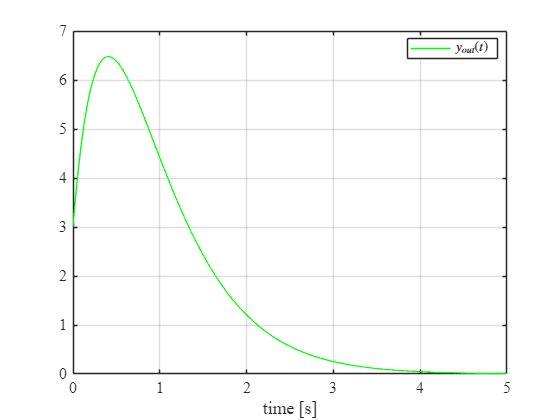

lambdas=[-2,-20,-200];

G = diag(lambdas)
Y = [1, 1, 2]


G =     -2     0     0
     0   -20     0
     0     0  -200


%%%%%%%%%%%%%%%% - nice

Y =      1     1     2


cvx_begin sdp
variable P(3,3)
A*P - P*G == B*Y;
cvx_end
K = -Y*pinv(P)
eig(A+B*K)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


%%%%%%%%%%%%%%%%

K =   425.8933 -387.0283  314.5183


ans =  -200.0000
  -20.0000
   -2.0000


t1 = 5;
time = linspace(0,t1,1000);
x0 = [1, 1, 1]';

D = 0;
Y = [1, 1, 1]
sys = ss(A+B*K, [0,0,0]', Y, [])
u = zeros(1, length(time));

Y =      1     1     1


[y_hat1, t1, x1] = lsim(sys, u, time, x0);

sys =
 
  A = 
          x1     x2     x3
   x1   4697  -4258   3474
   x2   2987  -2709   2208
   x3  -2987   2707  -2210
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, y_hat1, 'g', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$y_{out}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("ctrl_eigen2");

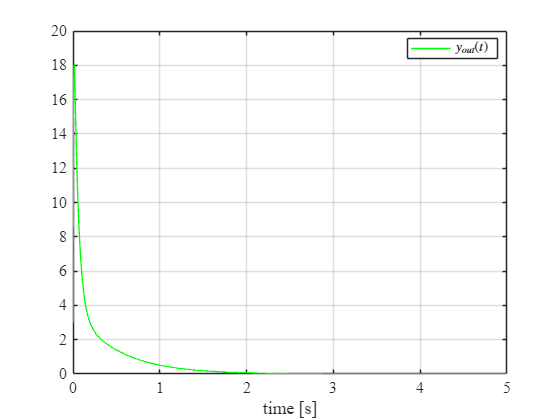

lambdas=[-2,-2-6i,-2+6i];


G = [-2    0  0;
      0   -2  6;
      0    -6 -2]
eig(G)
Y = [1, 1, 0]  % not working with Y = [1, 1, 2]

G =     -2     0     0
     0    -2     6
     0    -6    -2


ans =   -2.0000 + 6.0000i
  -2.0000 - 6.0000i
  -2.0000 + 0.0000i


%%%%%%%%%%%%%%%% - nice

Y =      1     1     0


cvx_begin sdp
variable P(3,3)
A*P - P*G == B*Y;
cvx_end
K = -Y*pinv(P)
eig(A+B*K)

 
Calling SDPT3 4.0: 7 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  7
 dim. of linear var  =  1
 dim. of free   var  =  7 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.1e+00|4.2e+02|4.5e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.988|1.7e-07|5.3e+00|1.2e+02| 0.000000e+00 -7.983348e+00| 0:0:00| chol  1  1 
 2|1.000|0.989|2.4e-08|6.8e-02|4.5e-01| 0.000000e+00 -8.443976e-02| 0:0:00| chol  1  1 
 3|1.000|0.989|3.8e-09|1.7e-03|4.1e-03| 0.000000e+00 -3.419334e-04| 0:0:00| chol  1  1 
 4|1.000|0.989|

%%%%%%%%%%%%%%%%

K =     4.4533   -5.0983    3.3283


t1 = 5;

ans =   -2.0000 + 6.0000i
  -2.0000 - 6.0000i
  -2.0000 + 0.0000i


time = linspace(0,t1,1000);
x0 = [1, 1, 1]';

D = 0;
Y = [1, 1, 1]
sys = ss(A+B*K, [0,0,0]', Y, [])
u = zeros(1, length(time));

Y =      1     1     1


[y_hat1, t1, x1] = lsim(sys, u, time, x0);

sys =
 
  A = 
           x1      x2      x3
   x1   60.99  -57.08   50.61
   x2   37.17  -35.69    29.3
   x3  -37.17   33.69   -31.3
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   1   1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, y_hat1, 'g', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$y_{out}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("ctrl_eigen3");

**Функция, чтобы сохранить картинку в папку**

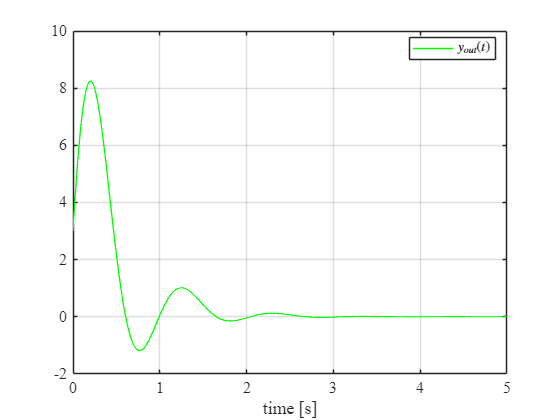

function save_file(name)

    path = 'D:\Math\control_theory\control_theory_labs\lab8\latex8\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end